# APフィルタ比較

## フィルタ長による比較

fleng     = 20;      %タップ数
fsize     = 520;    %フレームサイズ

lengthF = 5;
lengthInit = 10;

ssize = 0.0001;
po = 6;

Ni = 100;
Avgi = 30;
avgt = zeros(Avgi,1);
apt = zeros(Ni,1);
graphF = false;
mode = true; % true = white noise
             % false = pink noise



for i = 1:Ni
    
    fleng = lengthInit + i * lengthF;
    eval(['apfilt',num2str(i),' = dsp.AffineProjectionFilter(',...
        '''Length''',',fleng,','''ProjectionOrder''',', po,','''StepSize''',',','ssize',');']);
end

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp();

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

calcSsizeP = 2/sqrt(dp'*dp)

calcSsizeP = 0.0689

calcSsizeW = 2/sqrt(dw'*dw)

calcSsizeW = 0.0878


if graphF == true
    
    for i = 1:Ni
        eval(['TS',num2str(i),' = dsp.TimeScope(','''TimeSpan''',',1.1*fsize,',...
            '''TimeUnits''',',','''Seconds''',',','''YLimits''',...
            ',[-3 3],','''BufferLength''',',4*fsize,','''ShowLegend''',...
            ',true,','''ChannelNames''',', {','''Noisy signal''',',', '''err''','},',...
            '''Title''',',''',num2str(ssize(i)),''');']);
    end
    
end
TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

if mode == true
    for i = 1:Ni
        for j = 1:Avgi
            tic;
            eval(['[~,e',num2str(i),'] = apfilt',num2str(i),'(dw,xw);']);
            avgt(j) = toc;
            eval(['apfilt',num2str(i),'.reset;']);
        end
        apt(i) = mean(avgt);
        disp(num2str(i));
        if graphF == true
            eval(['TS',num2str(i),'([xw,e',num2str(i),']);'])
        end
    end
end

1


2


3


4


5


6


7


8


9


10


11


12


13


14


15


16


17


18


19


20


21


22


23


24


25


26


27


28


29


30


31


32


33


34


35


36


37


38


39


40


41


42


43


44


45


46


47


48


49


50


51


52


53


54


55


56


57


58


59


60


61


62


63


64


65


66


67


68


69


70


71


72


73


74


75


## ピンクノイズ

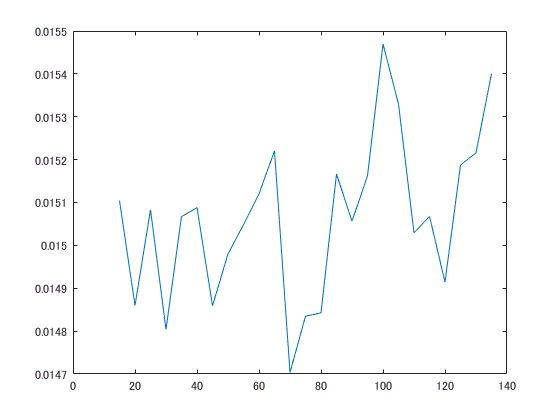

if mode == false
    for i = 1:Ni
        tic;
        eval(['[~,e',num2str(i),'] = apfilt',num2str(i),'(dp,xp);']);
        apt(i) = toc;
        if graphF == true
            eval(['TS',num2str(i),'([xp,e',num2str(i),']);'])
        end
    end
end
plot(lengthF+lengthInit:lengthF:fleng,apt);